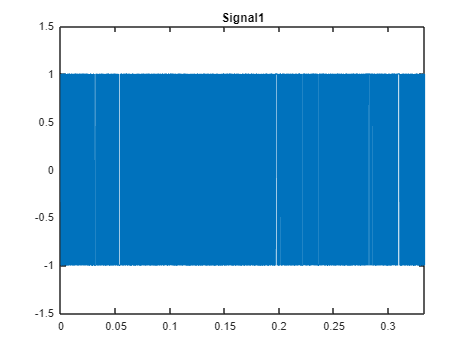

close all;
clear all;
%%
nb_bits = 2000;
bits = randi([0,1],1,nb_bits);
Fe = 24000; 
Rb = 6000;
T=1/Rb;
Ns= Fe/Rb % 24000 / 6000 = 4 


%Modulateur 1
Symboles1 = 2 * bits -1;
h = ones(1, Ns);

Suite_diracs1 = kron(Symboles1, [1 zeros(1,Ns-1)]);

SignalModule1 = filter(h,1,Suite_diracs1);

t = (0:length(SignalModule1)-1)/Fe;
figure('Name', 'Signal 1');
plot(t, SignalModule1);
axis([0 t(end) -1.5 1.5]);
title('Signal1');

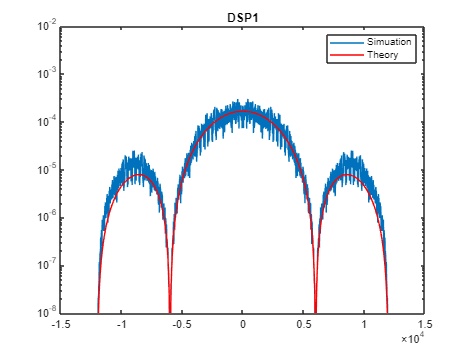


%Part of calulating and printing DSP1
figure;
DSP1_simulaire = pwelch(SignalModule1,[],[],[],Fe,'twosided', 'centered');
axis_freq = linspace(-Fe/2,Fe/2,length(DSP1_simulaire));
semilogy(axis_freq,DSP1_simulaire);
hold on;
V=1; %amplitude du signal  binaire
sigma_d = V.^2;
DSP1_theorique = (1/Rb) * (sigma_d)* sinc(axis_freq/Rb).^2; 
semilogy(axis_freq,DSP1_theorique,'r');
legend('Simuation','Theory')
title('DSP1');
ylim([1e-8,1e-2]);

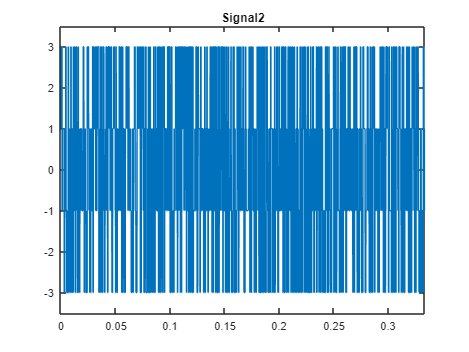

%Moulateur 2
bits_reshape = reshape(bits, 2, [])';

Symboles2 = (2*bi2de(bits_reshape) - 3)';
Ns2 =2*Ns; % Il faut 8 bits pour coder un symbol
Suite_diracs2 = kron(Symboles2, [1 zeros(1,Ns2-1)]);
h2 = ones(1, Ns2);
SignalModule2 = filter(h2,1,Suite_diracs2);
t2 = (0:length(SignalModule2)-1)/Fe;
figure('Name', 'Signal 2');
plot(t2, SignalModule2);
axis([0 t2(end) -3.5 3.5]);
title('Signal2');

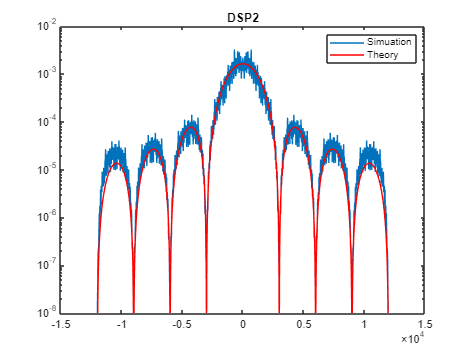


%Part of calulating and printing DSP2_Theorique
figure;
DSP2_simulaire = pwelch(SignalModule2,[],[],[],Fe,'twosided', 'centered');
axis_freq2 = linspace(-Fe/2,Fe/2,length(DSP2_simulaire));
semilogy(axis_freq2,DSP2_simulaire);
hold on;
V2=3; %amplitude du signal  binaire
T2=2/Rb;
sigma_d = 5;

DSP2_theorique = T2 * (sigma_d)* sinc(axis_freq2*T2).^2; 
semilogy(axis_freq2,DSP2_theorique,'r');
legend('Simuation','Theory')
title('DSP2');
ylim([1e-8,1e-2]);

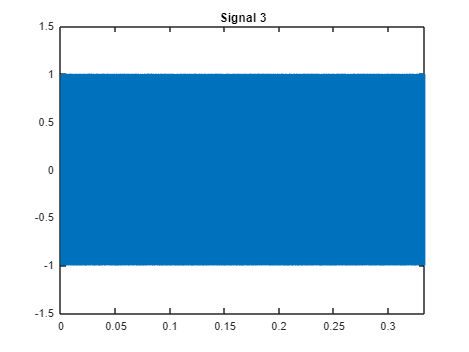


%Moulateur 3
Symboles3 = 2 * bits -1;
Suite_diracs3 = kron(Symboles3, [1 zeros(1,Ns-1)]);
h3 = [-ones(1, floor(Ns/2)) ones(1, ceil(Ns/2))];
SignalModule3 = filter(h3,1,Suite_diracs3);

t3 = (0:length(SignalModule3)-1)/Fe;
figure('Name', 'Signal 3');
plot(t3, SignalModule3);
axis([0 t3(end) -1.5 1.5]);
title('Signal 3');

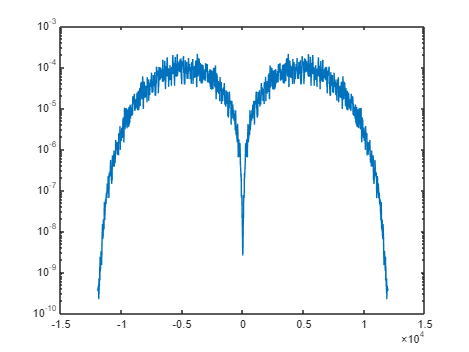

%Part of calulating and printing DSP3
figure;
DSP3_simulaire = pwelch(SignalModule3,[],[],[],Fe,'twosided', 'centered');
axis_freq3 = linspace(-Fe/2,Fe/2,length(DSP3_simulaire));
semilogy(axis_freq3,DSP3_simulaire);
hold on;

T3=1/Rb;
sigma_d = 1;

sigma_d = 1.0005

sigma_d1 = 1

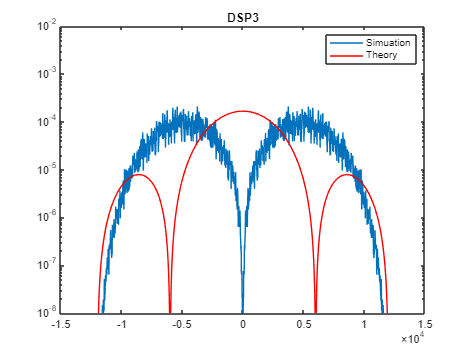

DSP3_theorique = T3 * (sigma_d)* sinc(axis_freq3*T3).^2;
semilogy(axis_freq3,DSP3_theorique,'r');
legend('Simuation','Theory')
title('DSP3');
ylim([1e-8,1e-2]);



%Moulateur 4
Symboles4 = 2 * bits -1;


Suite_diracs4 = kron(Symboles4, [1 zeros(1,Ns-1)]);
h4 = 2*rcosdesign(0.2,8,Ns,'sqrt');
SignalModule4 = filter(h4,1,Suite_diracs4);
figure('Name', 'Signal 4');


plot((0:(nb_bits*Ns - 1))/Rb, SignalModule4);
axis([0 (nb_bits*Ns - 1)/Rb -1.5 1.5]);
%Part of calulatting and printing DSP4_Simulaire
DSP4_simulaire = pwelch(SignalModule4,[],[],[],Fe,'twosided', 'centered');
axis_freq = linspace(-Fe/2,Fe/2,length(DSP4_simulaire));
semilogy(axis_freq,DSP4_simulaire);
hold on;
DSP4_theorique = ;
semilogy(axis_freq,DSP4_theorique,'r');
legend('Simuation','Theory')
title('DSP1');
ylim([1e-8,1e-2]);



%2
figure('Name', 'DSP-Simulaire');
semilogy(axis_freq,DSP1_theorique);
hold on;
semilogy(axis_freq,DSP2_theorique);
hold on;
semilogy(axis_freq,DSP3_theorique);
hold on;
semilogy(axis_freq,DSP4_simulaire);
title('Compare for DSP-Simulaire of each signal')
legend('Signal 1', 'Signal 2', 'Signal 3', 'Signal 4');
ylim([1e-8,1e-2]);

